# ECE 485/585 Midterm Exam Preparation Material, Study Guide and Hint 

### Review and thoroughly understand 

- [lecture slides](matlab:open('./Lectures 1-4.pdf'))

- [homework ](matlab:open('./HW 1-2.pdf'))

- [Extra Examples](matlab:open('./Examples.pdf'))

- [Quiz](matlab:open('./Quizes 1-4.pdf'))

- Reference Material 

## Thoroughly understand the different types of:

- Asynchronous I/O protocols [Lecture 2: page 20 - 22](matlab:open('./Lectures 1-4.pdf'))

- Given a timing diagram

- Discern between various types of asynchronous I/O protocols

- Describe advantages and disadvantages of each protocol. 

### SDRAM

#### Using a specified SRAM chip organization, construct a given memory system with a defined capacity  

#### Such as: 

- Draw out the block diagram;

- Understand how many ranks are needed for the memory system; 

- Understand how many chips are needed per rank;

- Understand how many such chips in total are needed;

- Know how many address signals are needed;

- Know the address, CS (Chip Select) and data signals connections. 

### 4

### DDR3

#### Capacity

Rows   =32e3;
Columns=256;
Banks  =8;
bits   =32;
Capacity = Rows*Columns*Banks*bits

Capacity = 2.0972e+09

#### 5. How many DDR3 chips are needed to create a non ECC DIMM and an ECC DIMM. 

### 6. Given the total number of refresh operation per a given refresh period, be able to calculate the total number of rows required to be refreshed for each refresh command. 

### 7. Calculate DIMM capacity with a given number of ranks per DIMM for a given DDR3 chip organization. 

### 8. Calculate maximum bandwidth of DIMM. 

    See slide “3-Memory-with Notes.pptx” page 83. 

### 9. Given a DDR3 chip timing

- Calculate the amount of time it takes to complete the read of a burst if all banks are precharged; 

        Time (in # of clock cycles) = tRCD + tCL + Burst Length/2

        Time (in seconds) = (tRCD + tCL + Burst Length/2) x clock cycle time 

- Calculate the average cycles or time needed to obtain the byte the CPU requested if the cache accessing the DRAM employed early restart. 

*                Early restart: as soon as the requested word arrives in the cache, send it to the processor and then continue reading the rest of the block into the cache. Note the byte can be in any of the burst; for example, if burst length = 8, the byte can be in any of the 1st, 2nd, 3rd, ..., 7th, 8th byte in the burst. (1+2+3+4+...+8)/8 = 36/8 = 4.5 burst on average, 4.5/2 = 2.25 clock cycle on average *

- Given a DDR3 chip timing, know how to calculate the average cycles or time needed to obtain the byte the CPU requested if the cache accessing the DRAM employed critical word first method. 

*                Critical word first: get the requested word first from the memory, send it as soon as possible to the processor and then continue reading the rest of the block into the cache. In critical word first, the desired byte would be among the 8 in the first chunk of the burst. *

### 10. Map a memory controller address bits to rank, bank, row, column, byte offset given a certain bits of physical address.See slide “3-Memory-with Notes.pptx” page 112. 

### 11. Understand memory page open and page closed policy. 

### 12. Understand the 8255 PPI

####         chip operation

####         how to figure out the I/O addresses of each port. 

### 13. Given a snippet of memory read and write mixture of operation with specified row, bank, column, burst order address bits, know how to re-arrange memory access such that it optimize the overall access time to reduce the latency and improve bandwidth.

General rules: 

Prioritize Read over Write if they are not from the same burst (meaning same row, same bank but different column addresses, a burst = 2n if there are n bit to specify burst order); 

- Read from an open row and open bank; 

- Avoid changing from Read to Write to Read. 

- Bank interleave 

Example: 

For the following CPU memory requests in a DDR3 memory controller’s queue, re-order the requests to reduce the overall latency and improve bandwidth.

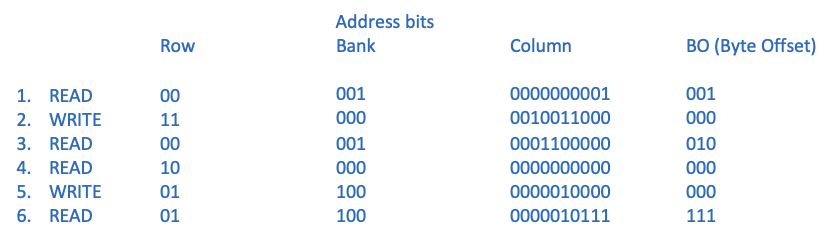

Move 3. READ ahead of 2. WRITE and after 1. (It’s to open row, same row as 1.).

Move 4. READ ahead of 2. WRITE (Read preferred).

Cannot move the 6. READ head of 5. WRITE (it’s the same burst, burst of 8), have to do write first before READ to ensure data is correct. 

Therefore final order should be: 1, 3, 4, 2, 5, 6 

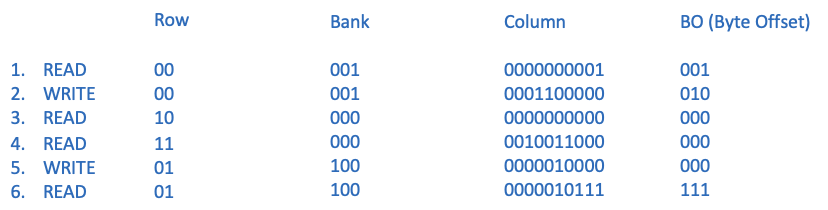

Burst Length of Various Memory Technology: 

SDR (SDRAM): BL = 1, 2, 4, 8 or “full page” DDR: BL = 2, 4, 8

DDR2: BL = 4, 8

DDR3: BL = 8 

DDR4: BL = 8

Notes: See lecture slide “3-Memory-with Notes.pptx” page 94. 